# Plot Results

clearvars
close all
%set(0,'defaulttextInterpreter','latex') %latex axis labels
%set(groot, 'defaultAxesTickLabelInterpreter','latex');
%set(groot, 'defaultLegendInterpreter','latex');
warning('off')

## Euclidean 3D

clearvars
close all
comebacktime3D=importfile("./SimulationResults/Euclidean3D/euclidean3D_0.tsv");
for i=1:7
    imp=importfile("./SimulationResults/Euclidean3D/euclidean3D_"+i+".tsv");
    comebacktime3D=cat(1,comebacktime3D,imp);
end

%comebacktime3D(comebacktime3D==-1)=0.01;
clear ans imp;
%[counts3D,edges3D] = histcounts(comebacktime3D,logspace(-2,log10(max(comebacktime3D)),120),'Normalization',"probability");
[counts3D,edges3D] = histcounts(comebacktime3D,20);
bin_middle3D=(edges3D(1:end-1)+edges3D(2:end))/2;
plot(bin_middle3D,counts3D,'.')
set(gca, 'xscale','log')
set(gca, 'yscale','log')
ylim([min(counts3D)*0.8,max(counts3D)*1.1])
xlabel("#walks until walker returns")
ylabel("probability p_0")

bin_middle3D_log=log10(bin_middle3D)';
counts3D_log=log10(counts3D)';

fit now the linear equation

[xData,yData]=prepareCurveData(abs(bin_middle3D_log),counts3D_log);
ft = fittype( 'poly1' );
excludedPoints = xData < 5;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;


% Fit model to data.
[fitresult, gof3D] = fit( xData, yData, ft,opts )

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -1.473  (-1.671, -1.274)
       p2 =        9.64  (8.508, 10.77)

gof3D = struct with fields:
           sse: 0.1287
       rsquare: 0.9433
           dfe: 15
    adjrsquare: 0.9395
          rmse: 0.0926


hold on
plot(10.^xData, 10.^(fitresult(xData)))
dim=fitresult.p1*(-2)

dim = 2.9452

dim_err=diff(confint(fitresult))

dim_err =     0.3974    2.2627


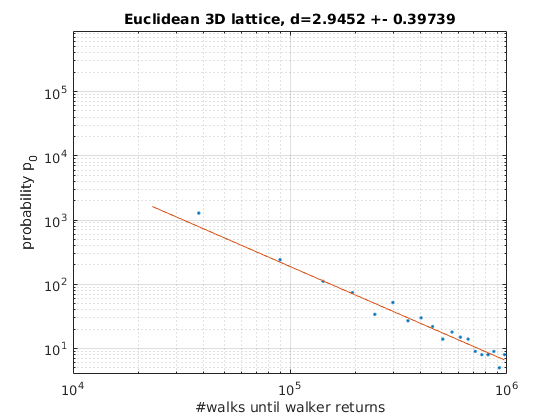

title("Euclidean 3D lattice, d="+dim+" +- "+dim_err(1))
grid on
grid minor

## Euclidean 2D

clearvars
close all
comebacktime2D=importfile("./SimulationResults/Euclidean2D/euclidean2D_0.tsv");
for i=1:7
    imp=importfile("./SimulationResults/Euclidean2D/euclidean2D_"+i+".tsv");
    comebacktime2D=cat(1,comebacktime2D,imp);
end

%comebacktime2D(comebacktime2D==-1)=0.01;
clear ans imp;
%[counts2D,edges2D] = histcounts(comebacktime2D,logspace(-2,log10(max(comebacktime2D)),50));
[counts2D,edges2D] = histcounts(comebacktime2D,200,'Normalization',"probability");
bin_middle2D=(edges2D(1:end-1)+edges2D(2:end))/2;
plot(bin_middle2D,counts2D,'.')
set(gca, 'xscale','log')
set(gca, 'yscale','log')
ylim([min(counts2D)*0.8,max(counts2D)*1.1])
xlabel("#walks until walker returns")
ylabel("probability p_0")

bin_middle2D_log=log10(bin_middle2D)';
counts2D_log=log10(counts2D)';

ft = fittype( 'poly1' );
excludedPoints = bin_middle2D_log < 4;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof2D] = fit( bin_middle2D_log, counts2D_log, ft,opts )

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -1.143  (-1.16, -1.126)
       p2 =       2.597  (2.502, 2.692)

gof2D = struct with fields:
           sse: 0.4142
       rsquare: 0.9890
           dfe: 195
    adjrsquare: 0.9890
          rmse: 0.0461


hold on
plot(bin_middle2D, 10.^(fitresult(bin_middle2D_log)))
dim=fitresult.p1*(-2)

dim = 2.2851

dim_err=diff(confint(fitresult))

dim_err =     0.0340    0.1904


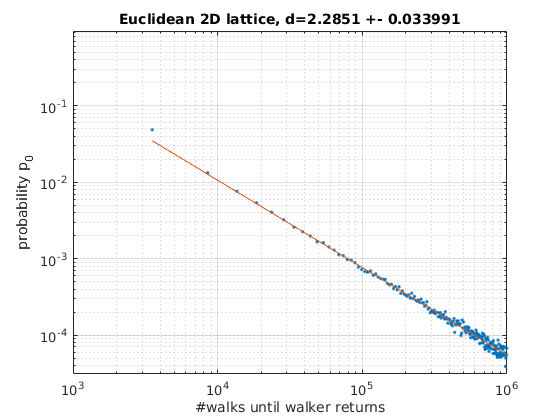

title("Euclidean 2D lattice, d="+dim+" +- "+dim_err(1))
grid on
grid minor

## Bethe Lattice

clearvars
close all
comebacktimeBL=importfile("./SimulationResults/BetheLattice/betheLattice_0.tsv");
for i=1:11
    imp=importfile("./SimulationResults/BetheLattice/betheLattice_"+i+".tsv");
    comebacktimeBL=cat(1,comebacktimeBL,imp);
end

clf
comebacktimeBL(comebacktimeBL==0)=0.01;
clear ans imp;
%[countsBL,edgesBL] = histcounts(comebacktimeBL,logspace(-2,log10(max(comebacktimeBL)),50));
[countsBL,edgesBL] = histcounts(comebacktimeBL,10,'Normalization',"probability");
bin_middleBL=(edgesBL(1:end-1)+edgesBL(2:end))/2;
plot(bin_middleBL,countsBL,'.')
%set(gca, 'xscale','log')
set(gca, 'yscale','log')
ylim([min(countsBL)*0.,max(countsBL)*1.2])
xlabel("#walks until walker returns")
ylabel("probability p_0")
xlim([min(bin_middleBL)*0.9,max(bin_middleBL)*1.01])

bin_middleBL_log=log10(bin_middleBL)';
countsBL_log=log10(countsBL)';

ft = fittype( 'poly1' );
excludedPoints = (bin_middleBL < 30)|(bin_middleBL>190);
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;
% Fit model to data.
[fitresult, gofBL] = fit( bin_middleBL', countsBL_log, ft,opts )

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    -0.03306  (-0.03538, -0.03075)
       p2 =      -1.314  (-1.581, -1.047)

gofBL = struct with fields:
           sse: 0.0995
       rsquare: 0.9951
           dfe: 6
    adjrsquare: 0.9943
          rmse: 0.1288


hold on
plot(bin_middleBL', 10.^(fitresult(bin_middleBL)))
dim=fitresult.p1*(-2)

dim = 0.0661

dim_err=abs(diff(confint(fitresult)))

dim_err =     0.0046    0.5348


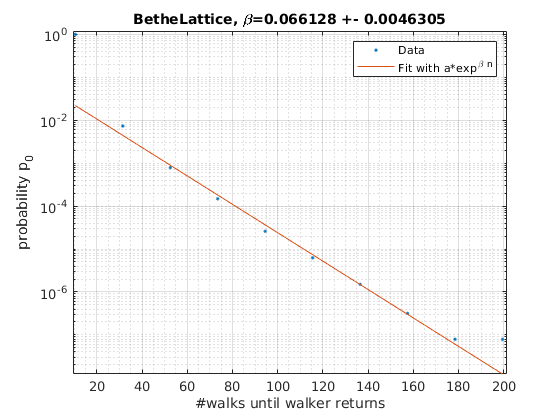

title("BetheLattice, \beta="+dim+" +- "+dim_err(1))
legend("Data","Fit with a*exp^{\beta n}")
grid on
grid minor

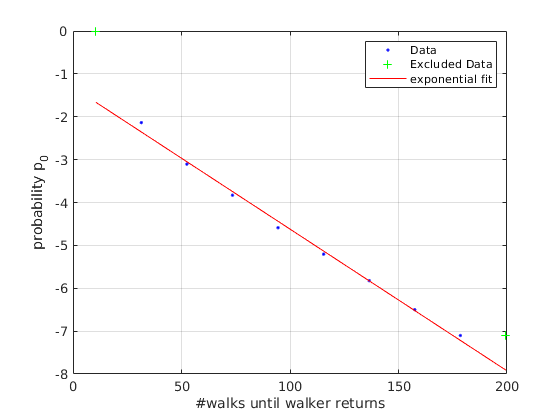

[xData, yData] = prepareCurveData( bin_middleBL, countsBL_log );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = (xData < 30) | (xData > 190);
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure();
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Data', 'Excluded Data', 'exponential fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel("#walks until walker returns")
ylabel("probability p_0")
grid on